# Testing april tag localization

## Initialize ros and take care of path:

init_matlab();

## Create cam object

calib_params = load("camera_calibration/calib_1024x768/cameraParams2.mat");
cam_intrinsics = calib_params.cameraParams2.Intrinsics;
cam = Camera_ROS(cam_intrinsics);

pause(1);

## get image from camera and display tag detection

img = rgb2gray(cam.get_image_raw());
[img_undistort, new_center] = cam.undistort_image(img);

img = rgb2gray(cam.get_image_raw());
% display april tag detection
try
    [num_tags, tag_ids, tag_img_corners, detected_tags] = AprilTags.detect_tags_in_image(img_undistort, cam_intrinsics);
    tag_area = polyarea(tag_img_corners(:,1), tag_img_corners(:,2));
    [img_undistort, new_center] = cam.undistort_image(img);
    img_tags_draw = AprilTags.draw_tags_on_image(img_undistort, cam_intrinsics, num_tags, tag_ids, tag_img_corners, detected_tags);
    figure
    imshow(img_tags_draw);
catch
    figure
    imshow(img_undistort);
end
% get tag in camera coords transform matrix
tag_ids
tag_idx = find(tag_ids == 18)
tag = detected_tags(tag_idx);
tag.T

if tag_idx
    % the transpose of T should be the cam in tag coords
    Tinv = tag.T^-1;
    
    cam_pose_tag_frame = Pose2d(Translation2d(-Tinv(4, 1), -Tinv(4, 3)), Rotation2d(Tinv(1,3), Tinv(3,3)).unary_minus);
    cam_pose_tag_frame.translation
    cam_pose_tag_frame.rotation
    
    % plot cam pose in tag frame
    figure; 
    quiver_pose(Pose2d.from_xydeg(0,0,90)); % plot tag pose tag frame
    hold on
    quiver_pose(cam_pose_tag_frame);        % plot cam pose tag frame
    
    legend("tag pose", "cam pose")
    axis equal
    ylim([0 8])
    xlim([-2 2])
end

## 2D Transforms

tag_pose = Pose2d.from_xydeg(1, 1, 0);
% tag_T_cam_frame = []
cam_pose_tag_frame = Pose2d.from_xydeg(0, 3, 150);
pan_rot = Rotation2d.from_degrees(90);

% offset of the tag pose from global origin
origin_to_tag = Transform2d.map_poses( ...
    Pose2d.from_xydeg(0,0,0), tag_pose);

% offset of the camera from tag origin
tag_to_camera = Transform2d.map_poses( ...
    Pose2d.from_xydeg(0,0,0), cam_pose_tag_frame);

% pose of the camera pan mount from robot origin
camera_to_robot = Transform2d.map_poses( ...
    Pose2d.from_xydeg(0,0,0), Pose2d.from_xyrot(0,0,pan_rot.unary_minus));

% apply the transforms to get from blank pose at origin in world frame
% to camera pose in world frame
cam_pose_world_frame = ...
    Pose2d.from_xydeg(0,0,0).transform_by(origin_to_tag).transform_by(tag_to_camera);
robot_pose_world_frame = ...
    Pose2d.from_xydeg(0,0,0).transform_by(origin_to_tag).transform_by(tag_to_camera).transform_by(camera_to_robot);


% plot poses (arrows are aligned with pose forward direction)
figure; hold on;

quiver_pose(tag_pose)
quiver_pose(cam_pose_world_frame)
quiver_pose(robot_pose_world_frame)

% plot styling
axis equal
xlim([0 5])
ylim([0 5])
legend("tag pose", "cam pose", "robot pose"); xlabel("x"), ylabel("y");

% create cam object
calib_params = load("camera_calibration/calib_1024x768/cameraParams2.mat");
cam_intrinsics = calib_params.cameraParams2.Intrinsics;
cam = Camera_ROS(cam_intrinsics);
pause(1);

r = rateControl(5);

% plotting stuff
f = figure; f.Position = [85,96,1290,492]; set(gcf,'Visible','on');
subplot(1, 2, 1); img_plot = imshow(zeros(768, 1024));
title("Minion View")
subplot(1, 2, 2);
title("Tag frame 2d plot"); legend("tag pose", "cam pose")

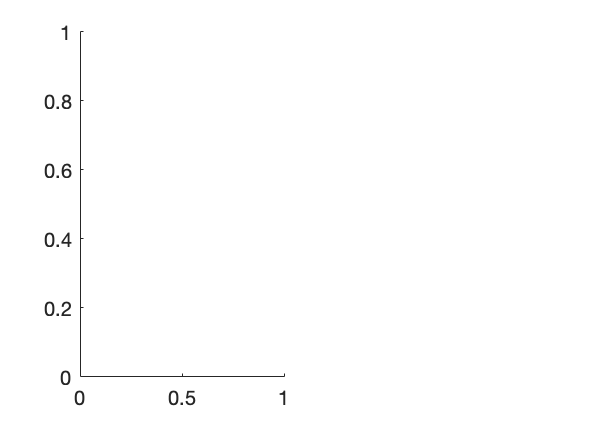

Error using matlab.graphics.primitive.Image/set
Invalid or deleted object.

Error in test_april_tag_ben>tag_localization_demo (line 151)
        set(img_plot, "Cdata", rgbImage);

axis equal; ylim([0 8]); xlim([-2 2])

while 1
%     cam_pose_tag_frame = get_cam_pose_tag_frame(cam, cam_intrinsics);
   cam_pose_tag_frame = tag_localization_demo(cam, cam_intrinsics, img_plot);
   waitfor(r);
end

function [cam_pose_tag_frame, tags_img] = get_cam_pose_tag_frame(img_undistort, cam_intrinsics)
%%CAM_POSE_TAG_FRAME returns a Pose2d of the camera's pose in an AprilTag's
%%frame of reference.

    % run april tag detection
    [num_tags, tag_ids, tag_img_corners, detected_tags] = ...
        AprilTags.detect_tags_in_image(img_undistort, cam_intrinsics);

    % return nan if tag 18 was not detected
    tag_idx = find(tag_ids == 18);
    if isempty(tag_idx)
        tags_img = img_undistort;
        cam_pose_tag_frame = [];
        Tinv = [];
        return
    end

    % Tag 18 was detected and we are proceeding
    tags_img = AprilTags.draw_tags_on_image(...
        img_undistort, cam_intrinsics, num_tags,...
        tag_ids, tag_img_corners, detected_tags);
    % get tag in camera coords transform matrix
    tag_18 = detected_tags(tag_idx);
    % the transpose of T should be the cam T in tag coords
    Tinv = tag_18.T^-1;
    
    % get camera pose in tag frame
    cam_pose_tag_frame = Pose2d(Translation2d(-Tinv(4, 1), -Tinv(4, 3)),...
        Rotation2d(Tinv(1,3), Tinv(3,3)).unary_minus);
end

function cam_pose_tag_frame = tag_localization_demo(cam, cam_intrinsics, img_plot)
%%CAM_POSE_TAG_FRAME returns a Pose2d of the camera's pose in an AprilTag's
%%frame of reference.
    % get undistorted img
    img = rgb2gray(cam.get_image_raw());
    [img_undistort, ~] = cam.undistort_image(img);
    
    % run april tag localization
    [cam_pose_tag_frame, tags_img] = get_cam_pose_tag_frame(img_undistort, cam_intrinsics);

    % if detection failed, just plot img
    if isempty(cam_pose_tag_frame)
        subplot(1, 2, 1) % switch to img subplot
        colormap bone
        rgbImage = ind2rgb(tags_img, colormap);
        set(img_plot, "Cdata", rgbImage);
        drawnow();
    else
    % if detection worked, plot the image with tag locations overlay and
    % do the space plot
        % display tag overlay img
        subplot(1, 2, 1) % switch to img subplot
        colormap bone
        set(img_plot, "Cdata", tags_img);
        drawnow();

        % update space plot
        subplot(1, 2, 2) % switch to space plot subplot
        quiver_pose(Pose2d.from_xydeg(0,0,90)); % plot tag pose tag frame
        hold on
        quiver_pose(cam_pose_tag_frame);        % plot cam pose tag frame
        legend("tag pose", "cam pose")
        axis equal
        ylim([0 8])
        xlim([-2 2])
        hold off

        drawnow();
    end
end

function quiver_pose(pose)
%     quiver(pose.translation.val_x, pose.translation.val_y,...
%        pose.rotation.vec_cos, pose.rotation.vec_sin, "LineWidth", 2);
%     
    pose_y = Pose2d(...
        pose.translation, pose.rotation.plus(Rotation2d.from_degrees(90)));
    quiver(pose_y.translation.val_x, pose_y.translation.val_y,...
       pose_y.rotation.vec_cos, pose_y.rotation.vec_sin, "LineWidth", 2);
end